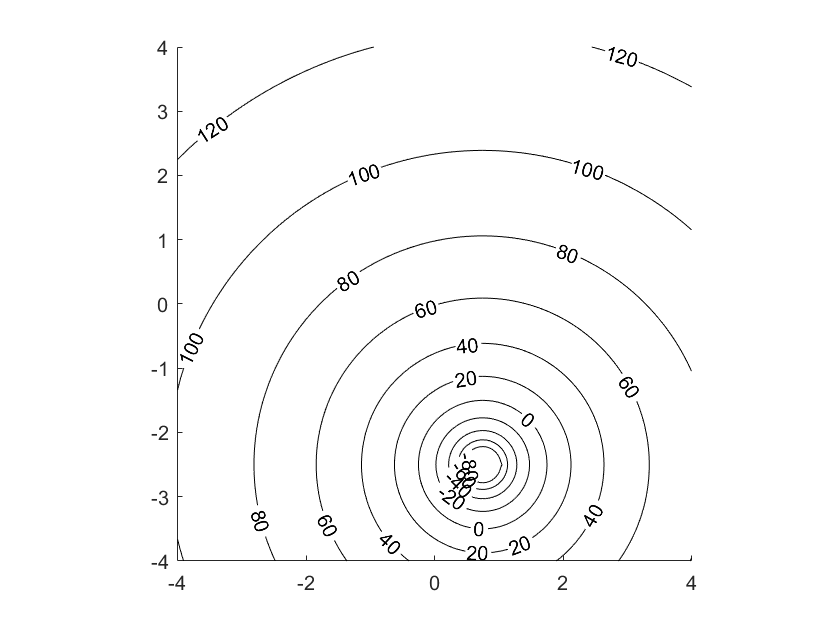

figure(2);
syms x y
[x,y]=meshgrid(-4:0.05:4,-4:0.05:4); clf; hold on;
f = 0;
grad = gradient(f, [x, y]);
% loop for BoB
for theta = 0:0.1:2*pi
    a = 0.25*cos(theta) + 0.75;
    b = 0.25*sin(theta) - 2.5;
    f = f + log(sqrt((x-a).^2+(y-b).^2));
end
grad = gradient(f, [x, y]);
% % loop for walls
% for a = -1.5:0.05:2.5
%     v = v - log(sqrt((x-a).^2) + (y-1).^2);
% end
% for a = -1.5:0.05:2.5
%     v = v - log(sqrt((x-a).^2) + (y+3.37).^2);
% end
% for b = -3.37:0.01:1
%     v = v - log(sqrt((x+1.5).^2) + (y-b).^2);
% end
% for b = -3.37:0.01:1
%     v = v - log(sqrt((x-2.5).^2) + (y-b).^2);
% end
contour(x,y,v,'k','ShowText','On')
axis equal

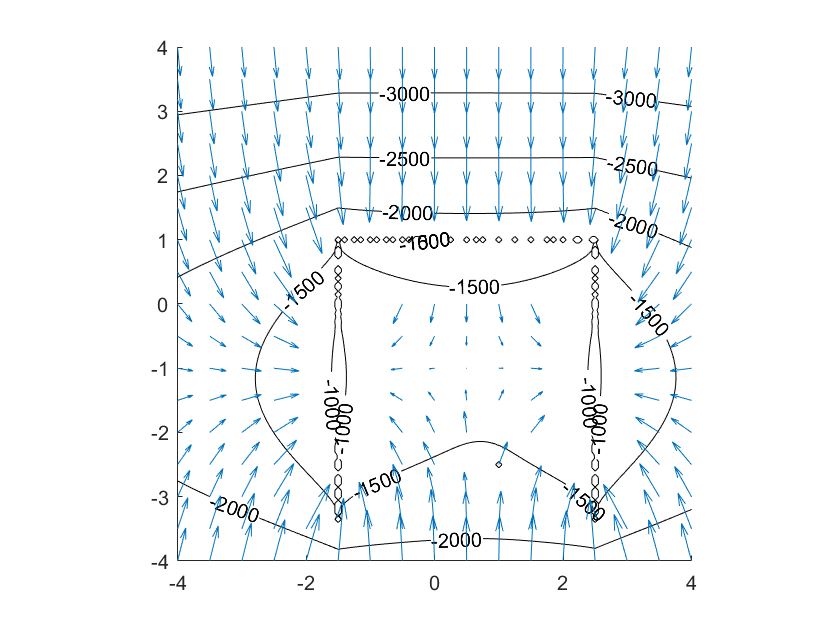

[x,y]=meshgrid(-4:0.5:4,-4:0.5:4); hold on;
v = 0;
% loop for BoB
for theta = 0:0.1:2*pi
    a = 0.25*cos(theta) + 0.75;
    b = 0.25*sin(theta) - 2.5;
    v = v + log(sqrt((x-a).^2+(y-b).^2));
end
% loop for walls
for a = -1.5:0.05:2.5
    v = v - log(sqrt((x-a).^2) + (y-1).^2);
end
for a = -1.5:0.05:2.5
    v = v - log(sqrt((x-a).^2) + (y+3.37).^2);
end
for b = -3.37:0.01:1
    v = v - log(sqrt((x+1.5).^2) + (y-b).^2);
end
for b = -3.37:0.01:1
    v = v - log(sqrt((x-2.5).^2) + (y-b).^2);
end

[fx, fy] = gradient(v);

figure(2); % quiver(x, y, fx, fy);
scale = 400;
quiver(x, y, fx/scale, fy/scale, 0)
axis equal

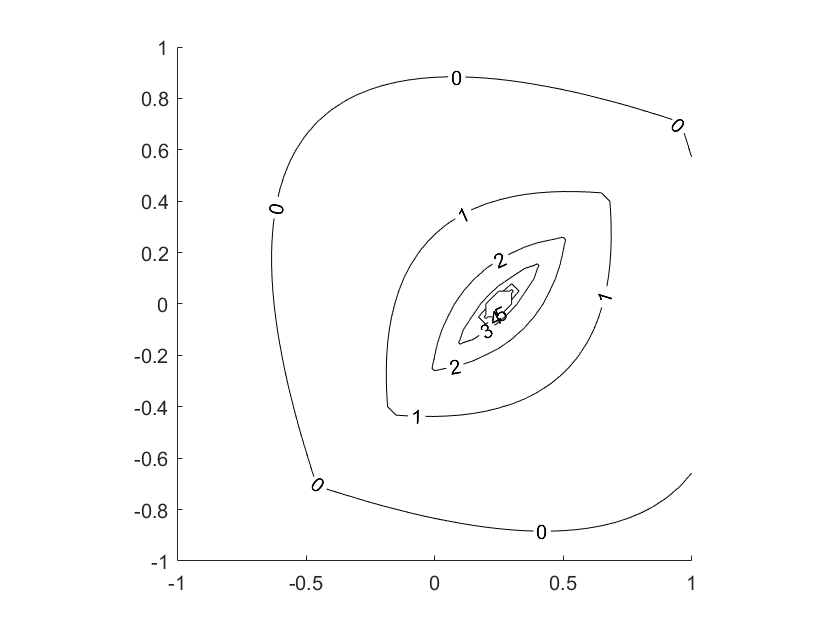

figure(); clf; hold on;
[x,y]=meshgrid(-1:0.05:1,-1:0.05:1);
v = 0;
% corners = [0 0 1 1 0;
%           0 1 1 0 0];
% for i = 1:4
%     a = corners(1,i)
%     b = corners(2,i)
%     
%     v = v - log(sqrt((x-a).^2) + (y-b).^2);
% end
% plot(corners(1,:), corners(2,:))
for a = -0.9:0.1:0.9
    delta_v = log(sqrt((x-a).^2) + (y-0).^2);
end
theta = 45;
for a = -0.25:0.05:0.25     % length 0.5 m
    rot_matrix = [cosd(theta) -sind(theta);
                  sind(theta) cosd(theta)];
    x_vector = x(:)';
    x_vector = x_vector - a*ones(size(x_vector));
    y_vector = y(:)';
    rotated_points = rot_matrix * [x_vector; y_vector];
    x_rot = reshape(rotated_points(1,:), [sqrt(length(rotated_points)), sqrt(length(rotated_points))]);
    y_rot = reshape(rotated_points(2,:), [sqrt(length(rotated_points)), sqrt(length(rotated_points))]);
    delta_v_2 = log(sqrt((x_rot).^2) + (y_rot).^2);
end

v = v - delta_v_2;
contour(x,y,v,'k','ShowText','On')
axis equal

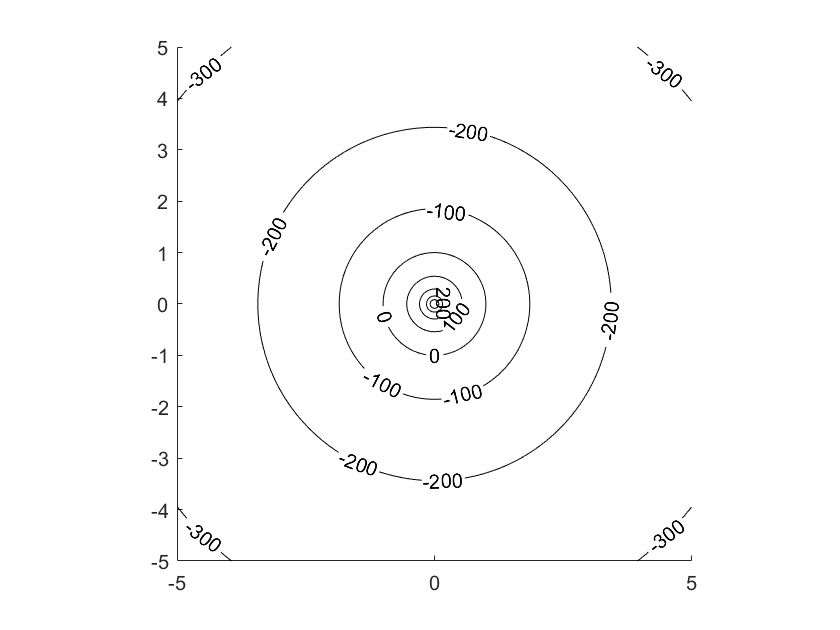

figure(2); clf;
[x,y]=meshgrid(-5:0.05:5,-5:0.05:5); clf; hold on;
v = 0;
for a = -1.5:0.05:2.5
    v = v - log(abs(x.^2+y.^2));
end
contour(x,y,v,'k','ShowText','On')
axis equal

syms x y
f = @get_delta_v;
z = f(x,y);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in draw_line (line 11)
        rotated_points = rot_matrix * [x; y];

Error in gauntlet>get_delta_v (line 94)
    d

BoB = function_handle with value:
    @(x,y)log10(sqrt((x-0.75).^2+(y+2.5).^2))


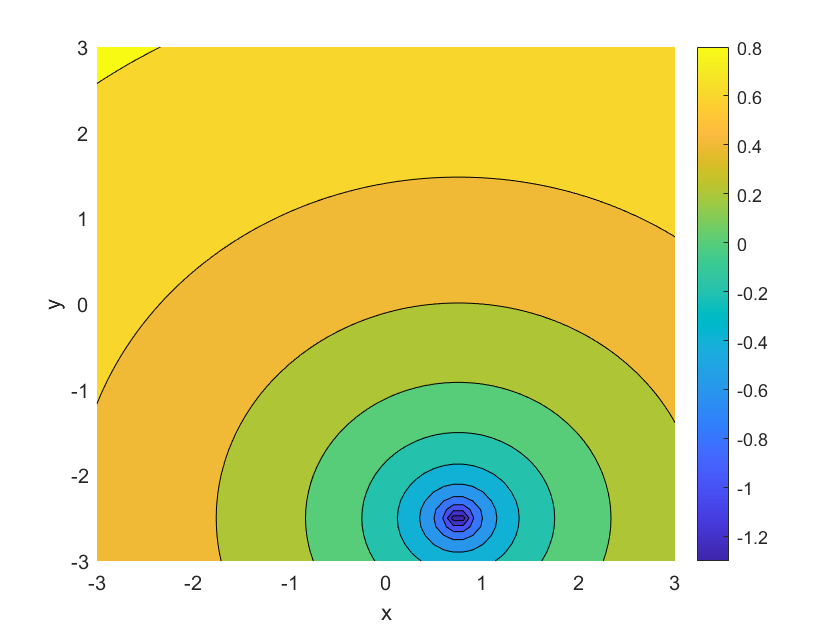

% Visualize
figure(1); clf; hold on;
contourf(x, y, z);
xlabel('x'); ylabel('y'); zlabel('z');
colorbar

function delta_v = get_delta_v(x, y)
    delta_v = draw_line(x, y, 0, 0, 45)
end